clearvars -except kg kg2 rkg k out

4:4 LD

k = 20           4:4 LD    MultiEigen4LD-April-26-2022-B

#### Plot unmodified amplitude data

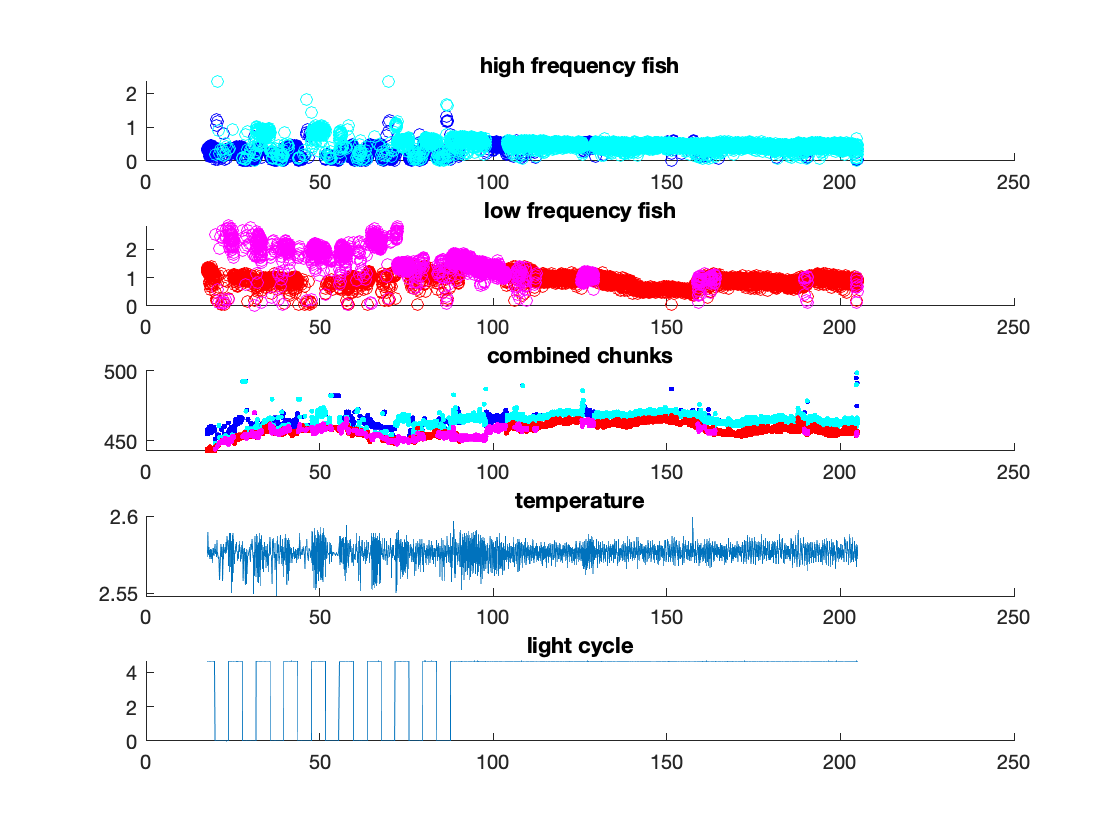

k_peakampmultiplotter(kg2(k).s);

#### Filter fish frequency errors

Click cutoff for eliminating erroneously low amplitude measurements.


Click cutoff for eliminating erroneously high amplitude measurements.


Click cutoff for eliminating erroneously low amplitude measurements.


Click cutoff for eliminating erroneously high amplitude measurements.


Click cutoff for eliminating erroneously low amplitude measurements.


Click cutoff for eliminating erroneously high amplitude measurements.


Click cutoff for eliminating erroneously low amplitude measurements.


Click cutoff for eliminating erroneously high amplitude measurements.


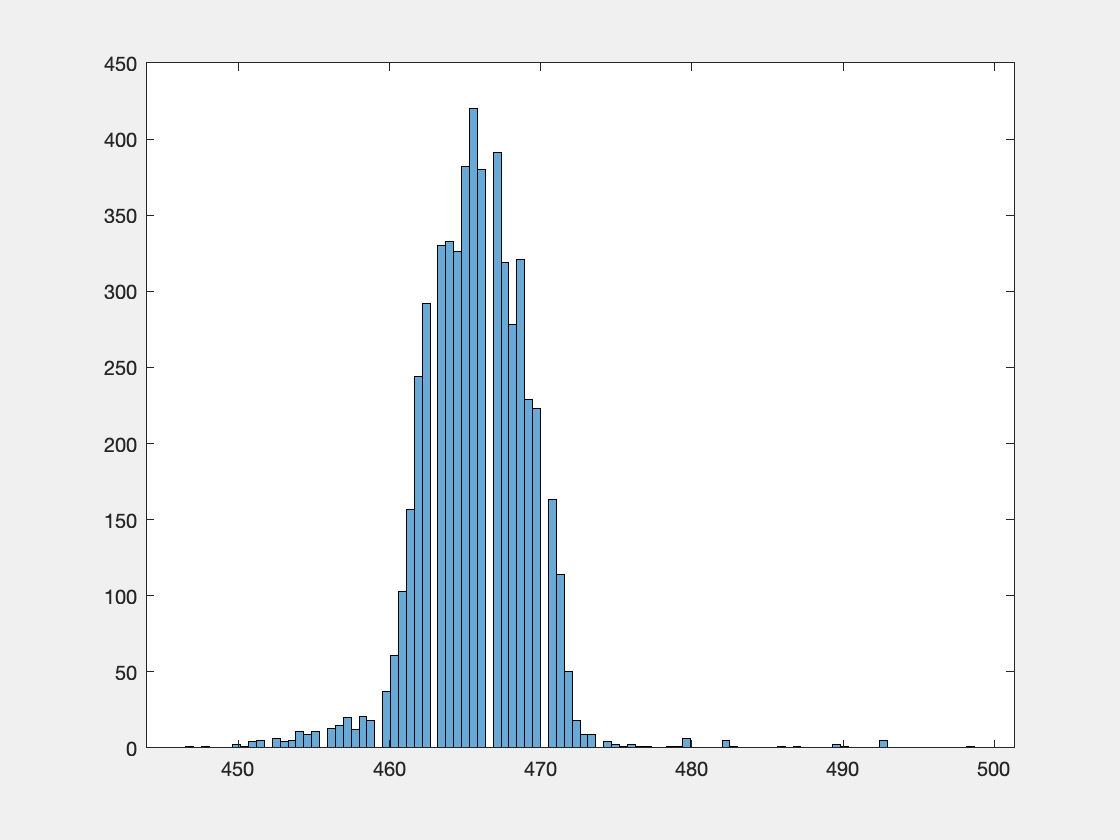

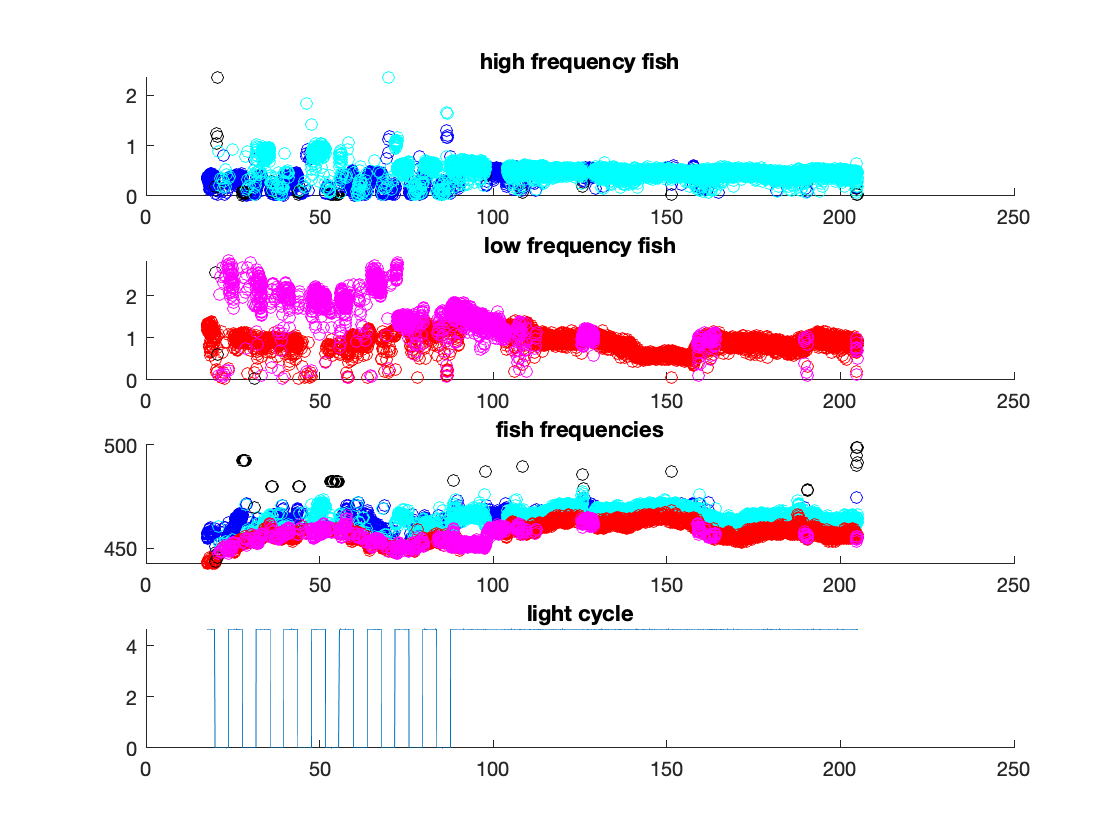

[hi, lo] = k_multifishfreqtrim(kg2(k).s);

hibackup = hi;
lobackup = lo;

hi = hibackup;
lo = lobackup;

thresh = k_fishcalplotter(hi, kg2(k).s, 'high frequency fish');

tube = 2;
%in = hi;

fishchunk1idx = find(hi(tube).tim < 72.5);
%     
        for j = 1:length(fishchunk1idx)
            hi(tube).pkampchunk1(j) = hi(tube).pkamp(fishchunk1idx(j))/2.3;
            hi(tube).obwampchunk1(j) = hi(tube).obwamp(fishchunk1idx(j))/2.3;
            
            hi(tube).timchunk1(j) = hi(tube).tim(fishchunk1idx(j));

        end

 fishchunk2idx = find(hi(tube).tim >= 72.5);
%     
        for j = 1:length(fishchunk2idx)
            hi(tube).pkampchunk2(j) = hi(tube).pkamp(fishchunk2idx(j))/1.2;
            hi(tube).obwampchunk2(j) = hi(tube).obwamp(fishchunk2idx(j))/1.2;
            
            hi(tube).timchunk2(j) = hi(tube).tim(fishchunk2idx(j));
        end
        

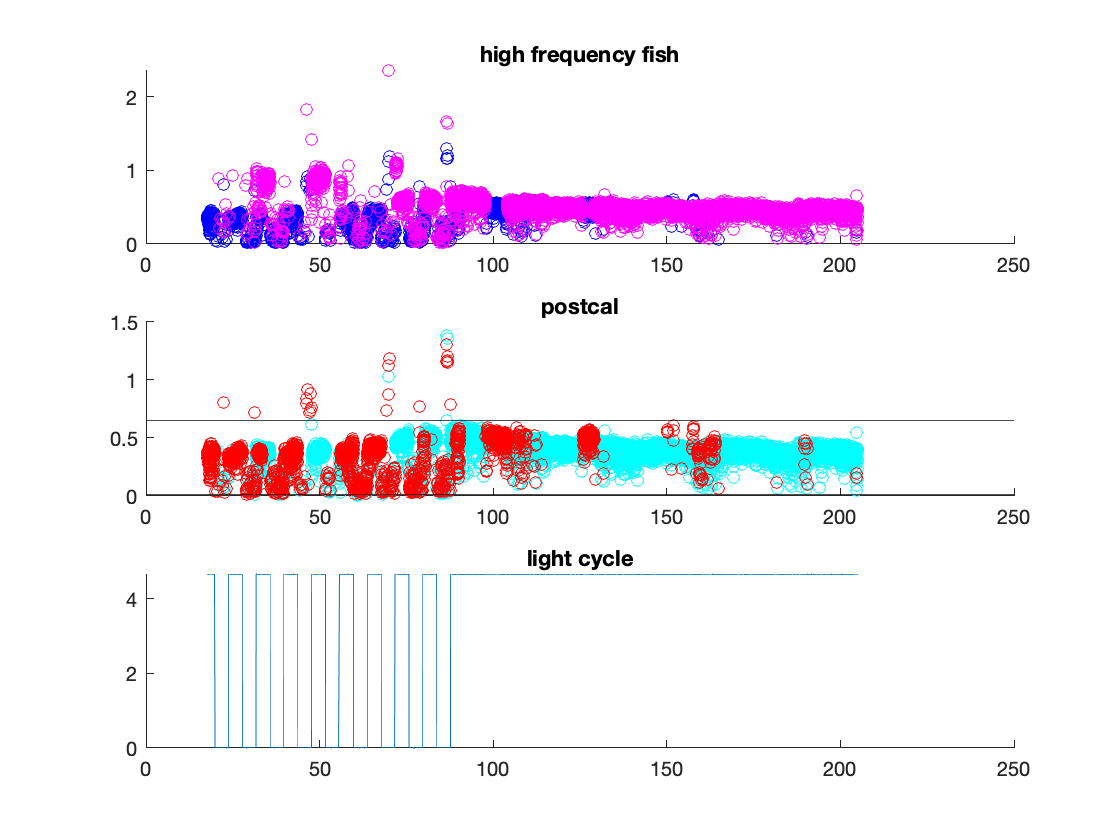

%check
k_fishcalchecker(hi, kg2(k).s,'high frequency fish', tube);

%save calibration
 hi(tube).pkamp = [hi(tube).pkampchunk1, hi(tube).pkampchunk2];
 hi(tube).obwamp = [hi(tube).obwampchunk1, hi(tube).obwampchunk2];
 hi(tube).tim = [hi(tube).timchunk1, hi(tube).timchunk2];

% sout = KatieFinalfishsplit(in)
kg2(k).hifish = KatieFinalfishsplit(hi);

Click cutoff for eliminating erroneously low amplitude measurements.


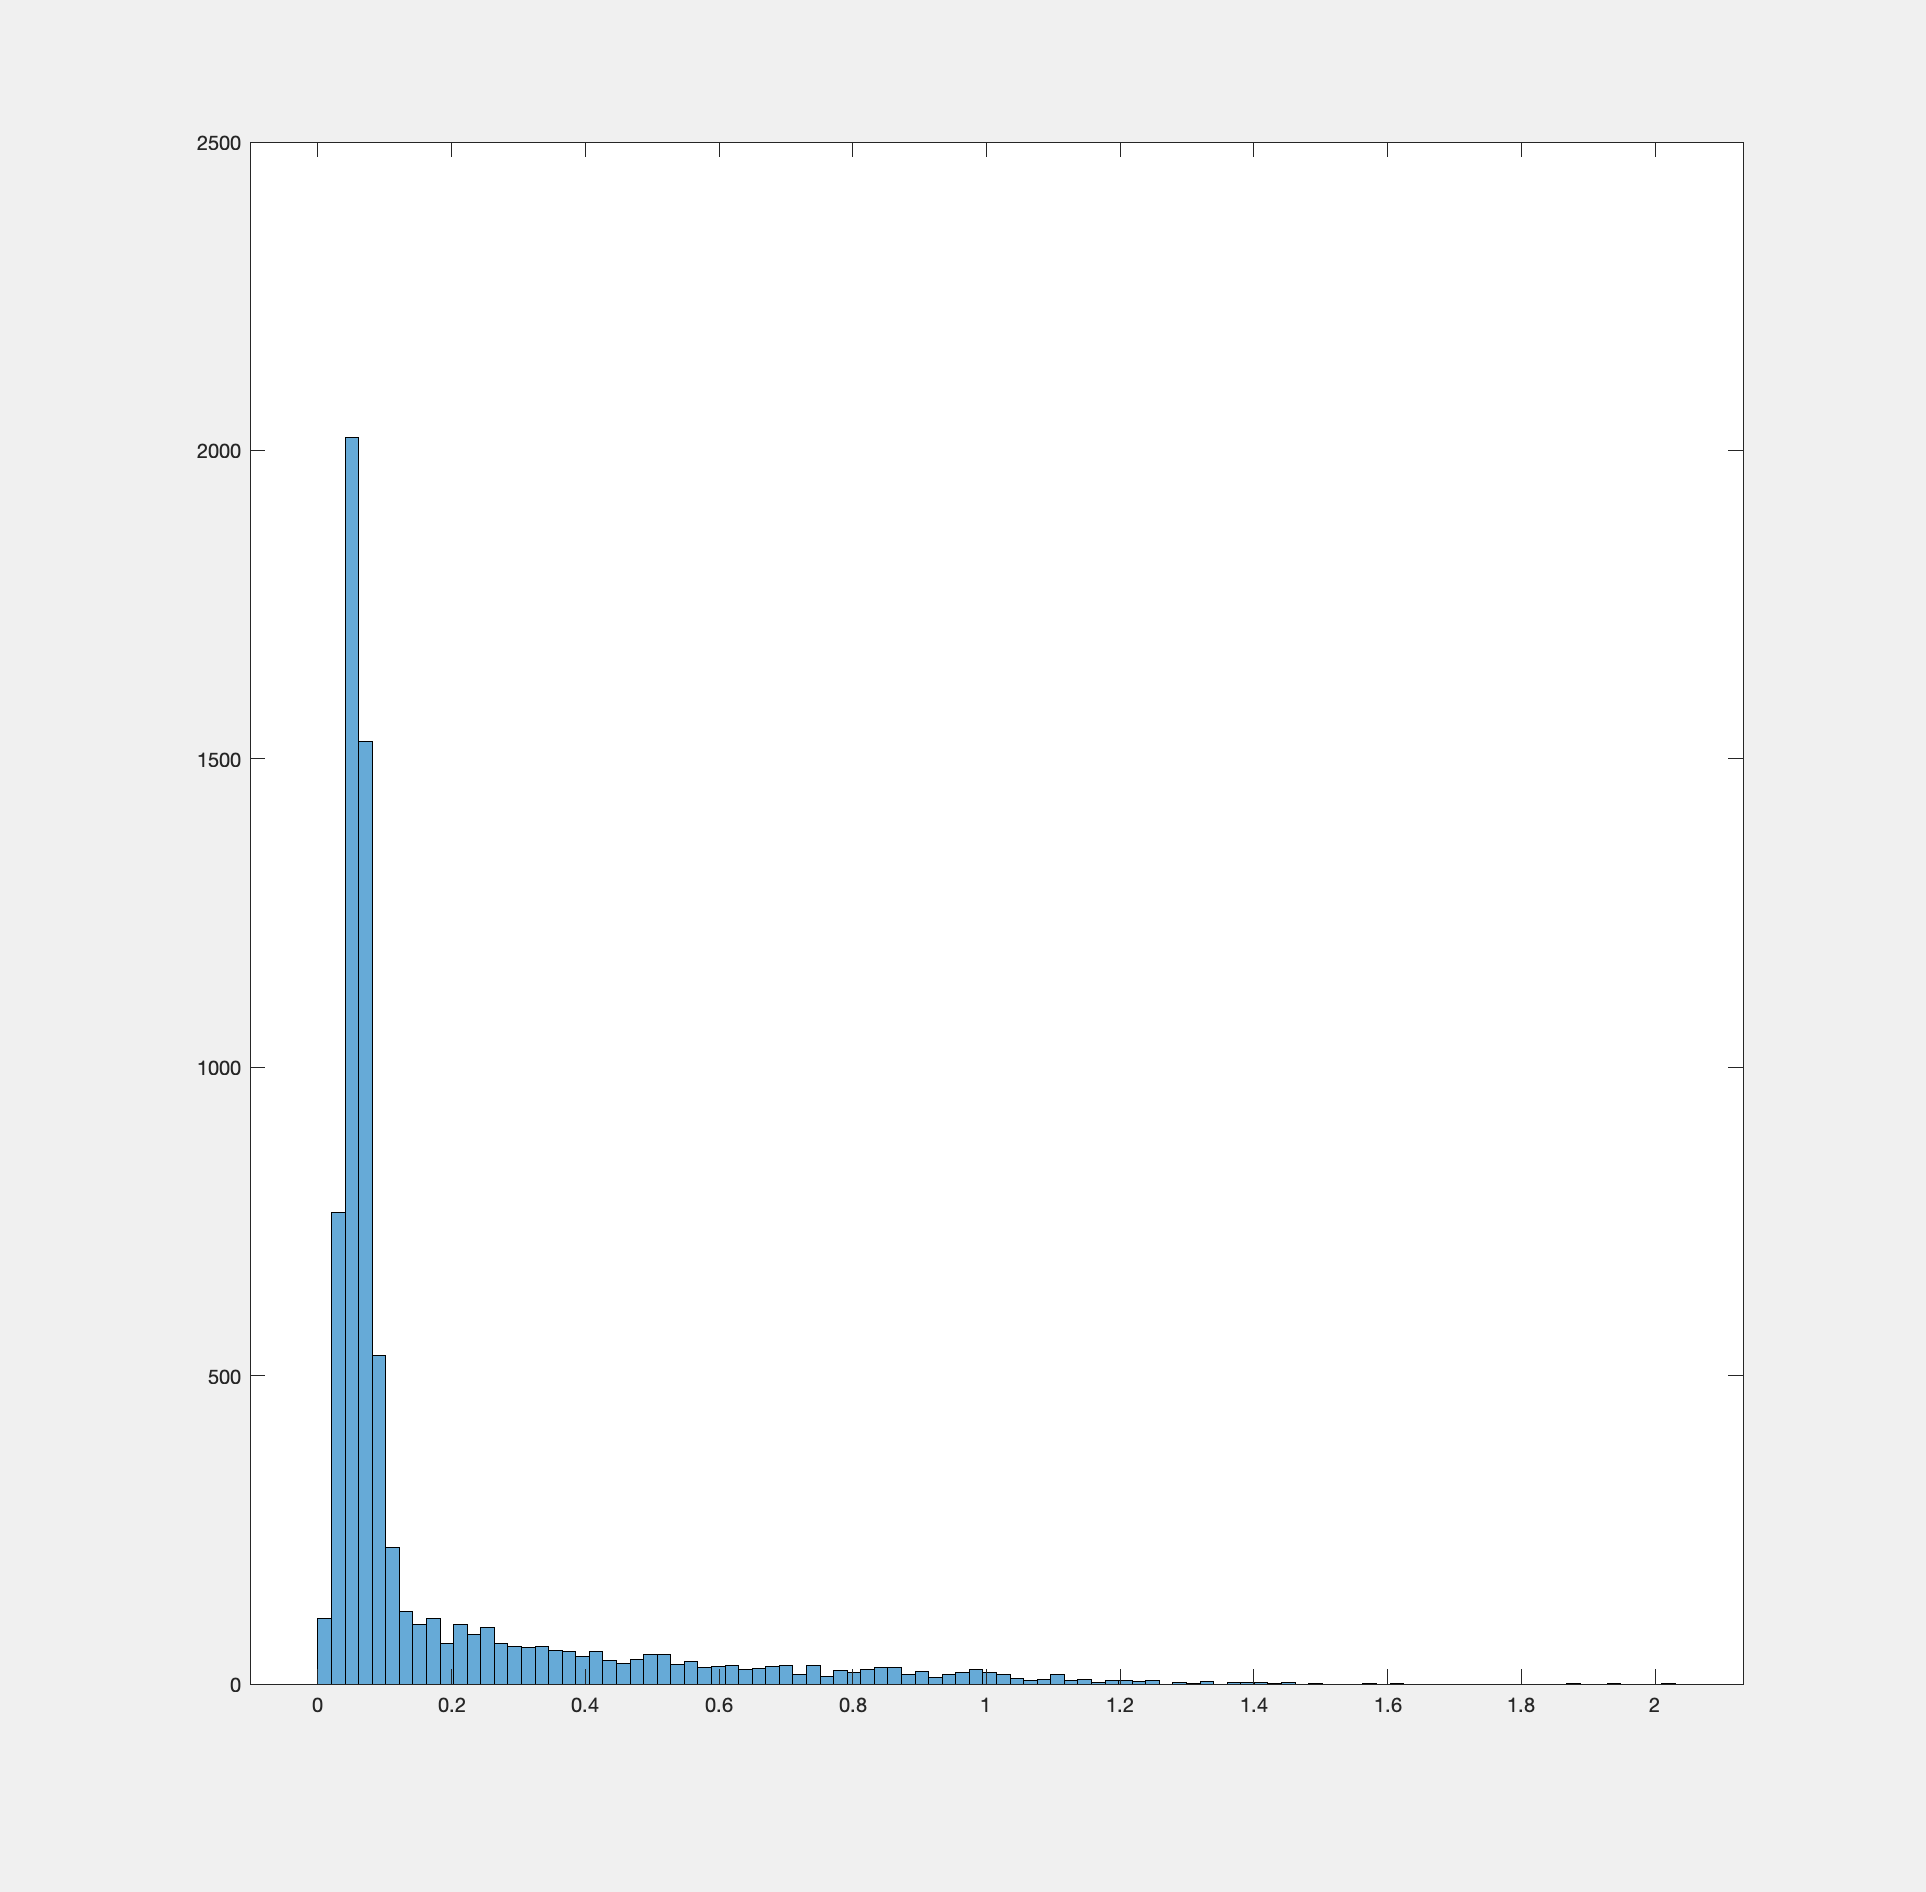

Error using ginput (line 81)
Interrupted

Error in KatiesingleMultiRemover (line 10)
    [cutofffreqL, ~]  = ginput(1);

%outlier removal
%low amplitude data means fish was not inside tube during recording
kg2(k).hiidx = KatiesingleMultiRemover(kg2(k).hifish, thresh);

%plot to check
k_removercheckplot(6, kg2(k)); 

%normalize to max value after removal
k_normcheckplot(6, kg2(k));



4:4 LD

k = 20           4:4 LD    MultiEigen4LD-April-26-2022-B